# Acoustic Tunnel ESM (directional with beam patterns)

Assuming that the array is fully convex, we can get away with no ray tracing at this point.

#### Show the starting geometry (no ESM) and setup variables

%import all of the array geometry
load("Sub Functions and Data\AcousticTunnelBasicGeometry.mat")

%generate (or load) a basic beam pattern, with rotation and spread 
load("Sub Functions and Data\BasicBeamLobe.mat")

%set/get the source location (for now set it as the most center point in
%the array, (which has an index), the try for different center points
sourceIndices = [round(size(arrayFullGeomData.fullArrayDataGeom,1)/2),round(size(arrayFullGeomData.fullArrayDataGeom,2)/2),round(size(arrayFullGeomData.fullArrayDataGeom,3)/2)];
sourceLoc = sourceIndices*arrayFullGeomData.pointSpacing;

%get/set the source vector
sourceVector = [1 0 0];

%set/get a basic source signal
sigFs = 5e5;
tSamp = 0:1/sigFs:3;

%a selection filter to only get a small part of the signal
selecSig = zeros(size(tSamp));
selecSig(1.5*sigFs:2*sigFs) = ones(size([1.5*sigFs:2*sigFs]));
%sourceSignal = selecSig.*sin(2*pi*1000*tSamp);
sourceSignal = 5000*sin(2*pi*1500*tSamp);

%TODO: write a function which generates a source of certain beam
%characteristics at a point and returns it's geometry
%transform the beam pattern so that it's facing the right direction and
%starting at the correct point

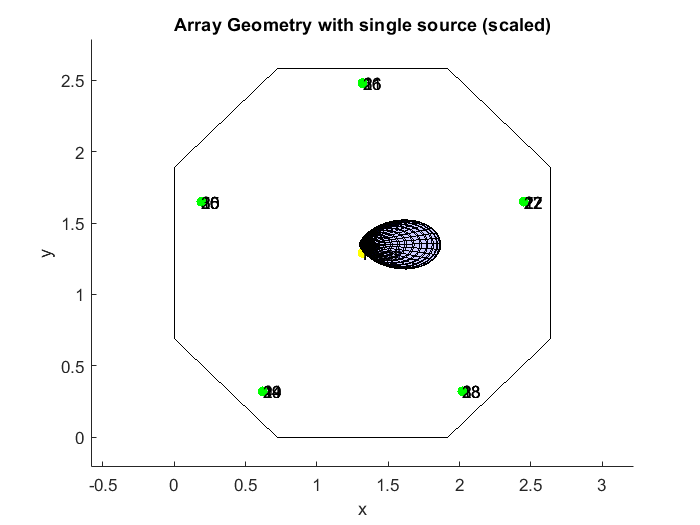

%show the source in the center of the array with all the geometry prepared
figure(1)
clf
hold on

%plot all the walls
for i = 1:7
    patch(arrayFullGeomData.rectangles(i,:,1),arrayFullGeomData.rectangles(i,:,2),arrayFullGeomData.rectangles(i,:,3),[1 0 0],"FaceAlpha",0.1);
end
    patch(arrayFullGeomData.rectangles(8,:,1),arrayFullGeomData.rectangles(8,:,2),arrayFullGeomData.rectangles(8,:,3),[1 0 0],"FaceAlpha",0.1);


%plot the microphones
text(arrayFullGeomData.micPositions(:,1),arrayFullGeomData.micPositions(:,2),arrayFullGeomData.micPositions(:,3),string([1:1:30]));
text(arrayFullGeomData.centerPoint(1),arrayFullGeomData.centerPoint(2),arrayFullGeomData.centerPoint(3) - 5,'Front')
text(arrayFullGeomData.centerPoint(1),arrayFullGeomData.centerPoint(2),arrayFullGeomData.centerPoint(3) + 5,'Rear')
scatter3(arrayFullGeomData.micPositions(:,1),arrayFullGeomData.micPositions(:,2),arrayFullGeomData.micPositions(:,3),'green','filled');

%plot the source
sourceScaleFactor = 200;
surf(sourceScaleFactor*X + sourceLoc(1),sourceScaleFactor*Y + sourceLoc(2),sourceScaleFactor*Z + sourceLoc(3),'FaceColor','blue','FaceAlpha',0.1);
scatter3(arrayFullGeomData.centerPoint(1),arrayFullGeomData.centerPoint(2),arrayFullGeomData.centerPoint(3),'yellow','filled');

title("Array Geometry with single source (scaled)")
xlabel('x')
ylabel('y')
zlabel('z')
axis equal

%set up the sources, the computation points and their associated data

%set up the total sources struct
sources = struct("sourceLocation",[],"sourceVector",[],"phi",[],"theta",[],"beamPattern",[],"sourceSignal",[]);
sources(1).sourceLocation = sourceLoc;
sources(1).sourceVector = sourceVector;
sources(1).phi = phi;
sources(1).theta = theta;
sources(1).beamPattern = basicGaus;
sources(1).sourceSignal = sourceSignal;

%set up the solution struct, a set of points for each time slice which we
%want to compute the solution for, these should corrospond to points in
%three dimensional space, but also have a geometrical representation
solutionPointsStruct = struct("solutionPointsVec",[],"solutionPointsGeomFull",[]...
    ,"solutionSliceXY",[],"solutionSliceXZ",[],"solutionSliceYZ",[]);

%set/get the times for which to compute (and store) the array response
%(lower sampling rate)
arrayTimeSlices = 0:0.01:3;

%set up the geometry to compute the acoustic field for, both the single row
%and geometry based
arrayVecGeometry = arrayFullGeomData.interiorArrayPointsUnordered;
arrayGeomGeometry = arrayFullGeomData.fullArrayDataGeom;

%TODO:
%also we can create points based on a radial spread from the source, this way
%we get a better plot of what the acoustic field will look like without
%annoying interpolation problems, note that we do this for the SLICES of
%the array

%TODO:
%precompute the solution structures and save them

#### Setup and show the ESM single reflection geometry, assuming perfect reflection and setup variables

%starting with the input beampattern, compute the output beampattern based
%on diffusivity and reflectiviy coefficients

%compute the positions of the reflected sources
reflectedSourcePoints = [];
for i = 1:size(arrayFullGeomData.arrayWallNorms,1)
    reflectedPoint = dot(sourceLoc - arrayFullGeomData.rectangleCenters(i,:),arrayFullGeomData.arrayWallNorms(i,:))*(-2*arrayFullGeomData.arrayWallNorms(i,:)) + sourceLoc;
    reflectedSourcePoints = [reflectedSourcePoints; reflectedPoint];
end

%compute the reflection vectors of the sources
reflectedVectors = [];
for i = 1:length(reflectedSourcePoints)
    reflecVec = sourceVector - 2*dot(sourceVector,arrayFullGeomData.arrayWallNorms(i,:)).*arrayFullGeomData.arrayWallNorms(i,:);
    reflectedVectors = [reflectedVectors;reflecVec];
end

%add to the source vector struct
for i = 2:length(reflectedSourcePoints)
    sources(i).sourceLocation = reflectedSourcePoints(i,:);
    sources(i).sourceVector = reflectedVectors(i,:);
    sources(i).phi = phi;
    sources(i).theta = theta;
    sources(i).beamPattern = basicGaus;
    sources(i).sourceSignal = sourceSignal;
end

#### Compute the acoustic field for stationary sources

%for each of the sources, pre-compute important factors such as the phase
%delay and other factors

%struct to hold the source data
preCompSourceData = struct("sourceDistances",[],"ampDecay",[],"phaseDelay",[],"beamPattDecay",[]);

%loop through each of the sources
for src = 1:size(sources,1)
    
%     %compute the rotation matrix to compute the rotation of a point 
%     %back into the correct phi and theta frame where the beam pattern is
%     %defined
%     %get the angle between the direction of the bat and the x axis
%     angleToRotate = acos(dot(sources(src).sourceVector,[1;0;0])/(norm(sources(src).sourceVector)));
%     
%     %get the axis to rotate around, cross the x axis with the direction of the
%     %bat
%     axisToRotate = cross(sources(src).sourceVector,[1;0;0]);
%     axisToRotate = axisToRotate/norm(axisToRotate);
%     
%     %get the rotation matrix
%     rotationMatrix = rotationVectorToMatrix(angleToRotate*axisToRotate);
    
    %note that once we apply the rotation matrix to the points
    rotatedArrayPoints = arrayVecGeometry;%*rotationMatrix;
    
    %now we convert from the rotated points into spherical 
    [arrPtsTh,arrPtsRo,arrPtsR] = cart2sph(rotatedArrayPoints(:,1),rotatedArrayPoints(:,2),rotatedArrayPoints(:,3));
    
    %now we compute the beam pattern decay for each theta and ro value
    %using an interpolation
    beamPattDecay = interp2(sources(src).theta,sources(src).phi,100000*sources(src).beamPattern,arrPtsTh + pi,arrPtsRo + pi);
    
    %compute the distance of each point to the source
    sourceDistances = vecnorm(arrayVecGeometry - sources(src).sourceLocation,2,2);
    
    %compute the radial amplitude decay for each point
    pointAmplitudeDecay = 1./(sourceDistances.^2);
    
    %compute the phase delay of each of the points based on the
    %distance, this is nothing but the distance divided by the speed of
    %sound to find the time delay, then divide by the sampling rate to
    %find the sample delay, note that each point we start at that
    %negative index for the sample delay, then increase the sample for
    %each time step
    phaseDelay = round(-1*(sourceDistances/331.5)/(1/sigFs));
    
    %now save all the data
    preCompSourceData(src).sourceDistances = sourceDistances;
    preCompSourceData(src).ampDecay = pointAmplitudeDecay;
    preCompSourceData(src).phaseDelay = phaseDelay;
    preCompSourceData(src).beamPattDecay = beamPattDecay;
end


%now actually add the contribution of each source to the acoustic field
%for each of the timesteps
for tStep = 1:length(arrayTimeSlices)
    
    %set up the solution points vector
    solPointsVector = ones([size(arrayVecGeometry,1), 1]);
    
    %set up the solution points physical locations
    solPointsGeom = arrayGeomGeometry;
    
    %compute how many samples have passed by at this time slice
    numSamplesPassed = round(arrayTimeSlices(tStep)/(1/sigFs));
    
    %for each of the sources
    for src = 1%:size(sources,1)
        
        %compute the signal based on the phase delay from that source
        pointDelays = preCompSourceData(src).phaseDelay + numSamplesPassed;
        pointDelays(pointDelays <= 0) = 1;
        pointDelays(pointDelays > length(sources(src).sourceSignal)) = 1;
        
        %the signal value at each location
        sigValsAtLocation = sources(src).sourceSignal(pointDelays);
        
        %compute the contrubution from each source 
        sourceContrib = preCompSourceData(src).ampDecay.*sigValsAtLocation'.*preCompSourceData(src).beamPattDecay;
        
        %add to the total array
        solPointsVector = solPointsVector + sourceContrib;
        
        %TODO:do the same thing for the geometrical data we have
        
    end
    
    %we have all the data, but to stop us from running out of memory, we
    %can just save the points for which we want a solution for
    %either this, or write the solution data directly to the disk in some
    %format
    solutionPointsStruct(tStep).solutionPointsVec = solPointsVector;

end


#### Display the acoustic field over time for the important slices

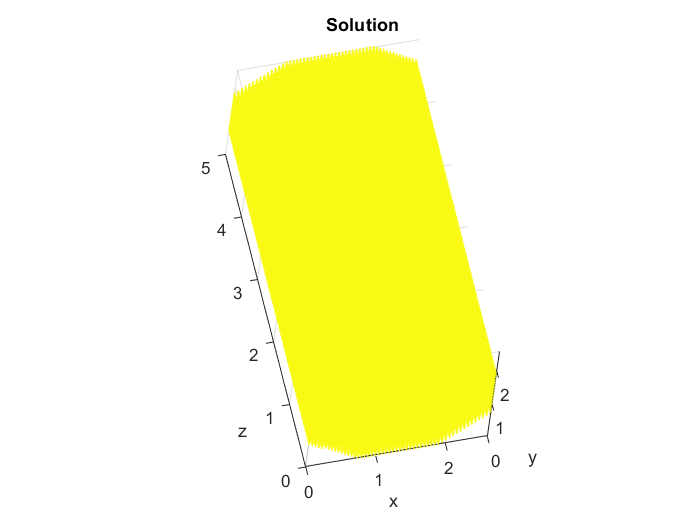

%get a single solution
singleSolution = solutionPointsStruct(10).solutionPointsVec;

%get the array points
interiorArrayPoints = arrayFullGeomData.interiorArrayPointsUnordered;

%set the size and color based on the proximity
figure(2)
clf
scatter3(interiorArrayPoints(:,1),interiorArrayPoints(:,2),interiorArrayPoints(:,3),1,1000*singleSolution);
xlabel('x')
ylabel('y')
zlabel('z')
camorbit(45,-5,'camera')
axis equal
title("Solution")

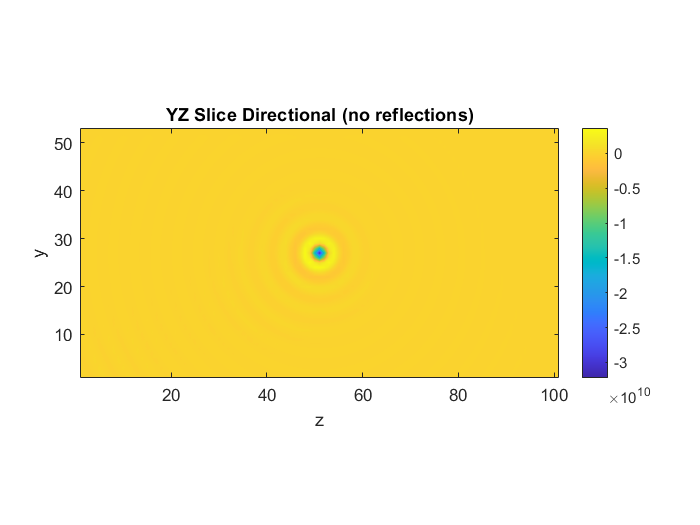

%reassign and take a slice
%TODO: do the same for the geometry case
%take some slices, make sure it goes through the midplane, x y and z
%convert the points back to indices
interiorArrayIndices = arrayFullGeomData.interiorArrayIndices;%round(arrayFullGeomData.interiorArrayPoints/arrayFullGeomData.pointSpacing);
interiorArrayIndices(interiorArrayIndices == 0) = 1;
fullData = zeros(size(arrayFullGeomData.fullArrayDataGeom));

%set all the data
for i = 1:size(interiorArrayIndices,1)
    fullData(interiorArrayIndices(i,1),interiorArrayIndices(i,2),interiorArrayIndices(i,3)) = singleSolution(i);
end

%get a slice
figure(4)
clf
contourf(1000*squeeze(fullData(25,:,:)),1000,'LineStyle','none');
title('YZ Slice Directional (no reflections)')
axis equal
colormap("parula")
colorbar
xlabel('z')
ylabel('y')

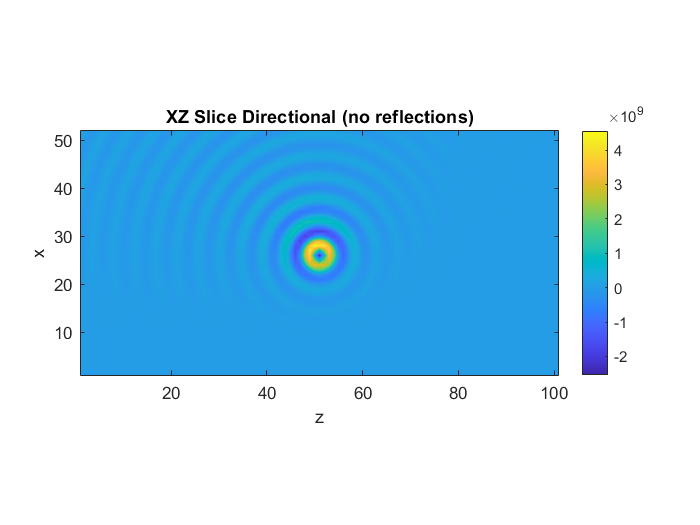


contourf(1000*squeeze(fullData(:,25,:)),1000,'LineStyle','none');
title('XZ Slice Directional (no reflections)')
axis equal
colormap("parula")
colorbar
xlabel('z')
ylabel('x')

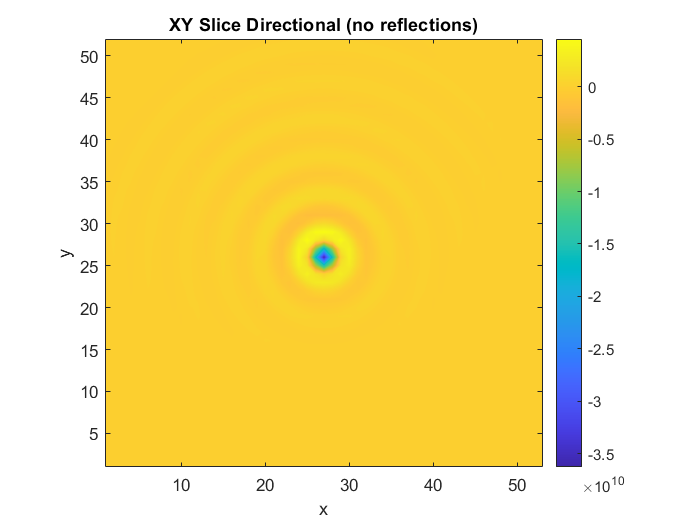



contourf(1000*squeeze(fullData(:,:,50)),1000,'LineStyle','none');
title('XY Slice Directional (no reflections)')
axis equal
colormap("parula")
colorbar
xlabel('x')
ylabel('y')